Here we look for a root of $x+\cos(10x)$ that is close to 1. 

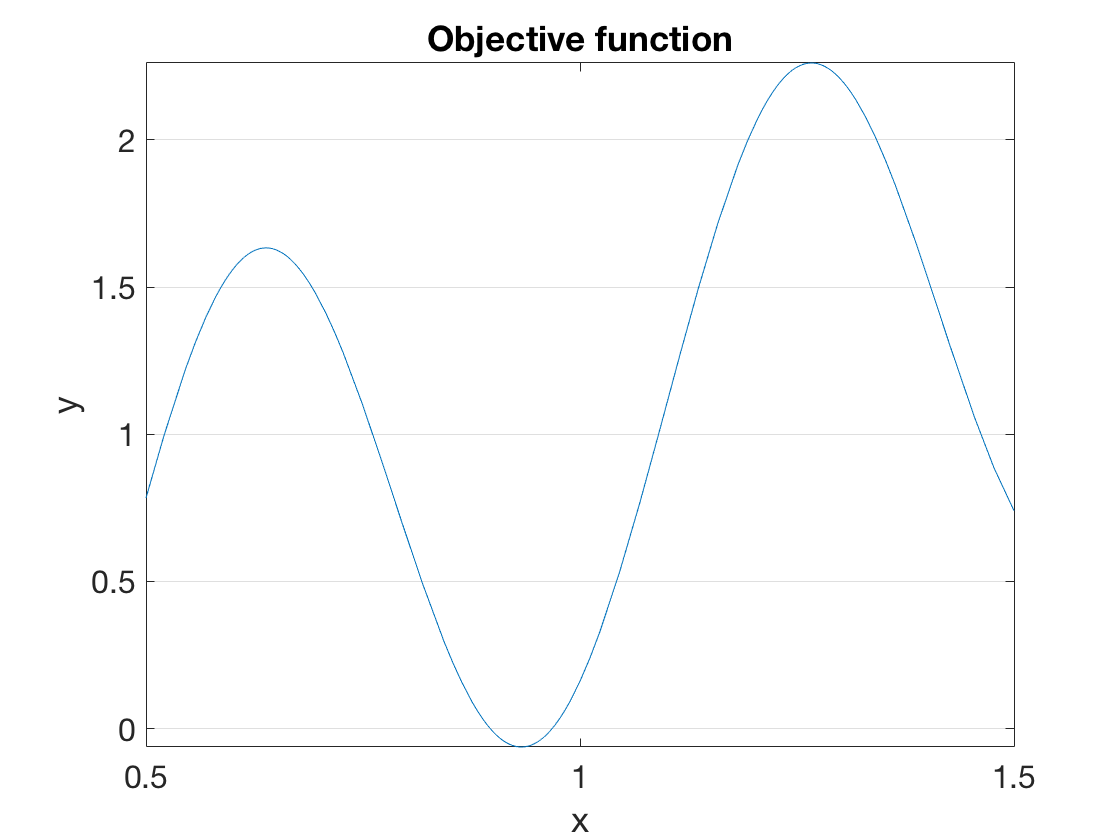

f = @(x) x + cos(10*x);
interval = [0.5,1.5];
fplot(f,interval)
set(gca,'ygrid','on'), axis(axis)   % ignore this line
title('Objective function')    % ignore this line
xlabel('x'), ylabel('y')    % ignore this line

r = fzero(f,1)

r = 0.9679

We choose three values to get the iteration started.

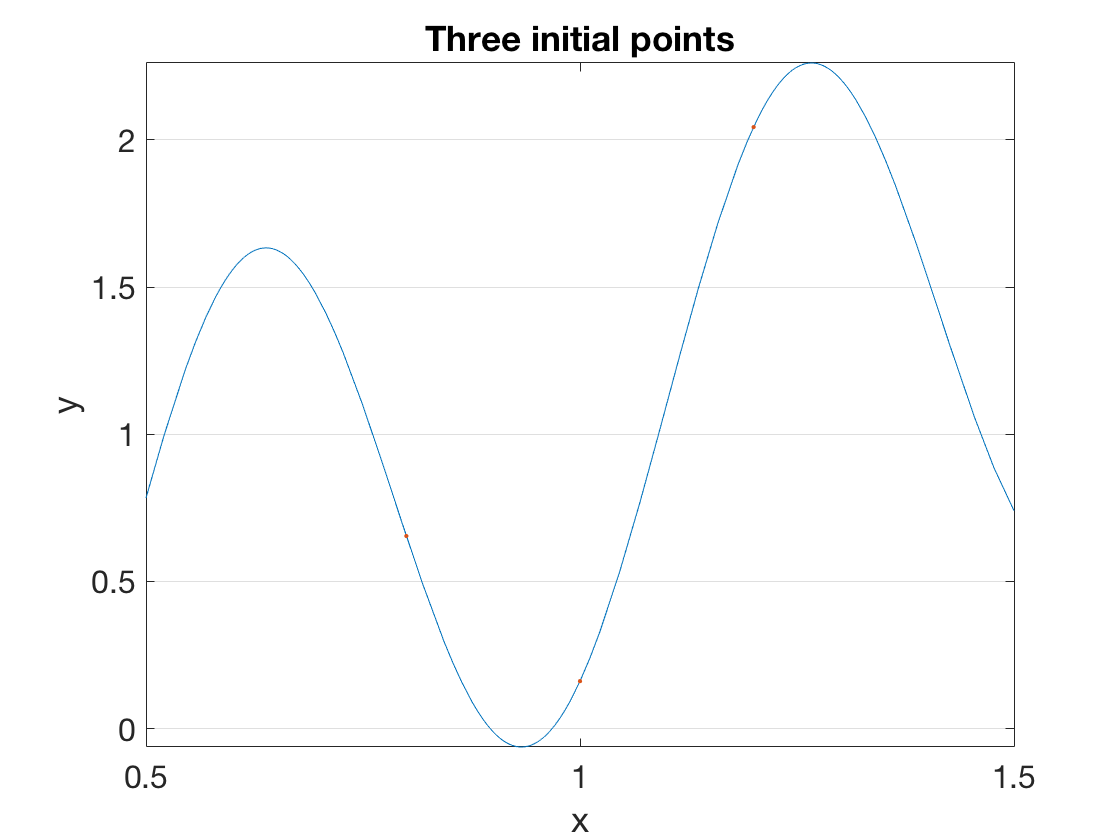

x = [0.8 1.2 1]';
y = f(x);
hold on, plot(x,y,'.')
title('Three initial points')    % ignore this line

If we were using "forward" interpolation, we would ask for the polynomial interpolant of $y$ as a function of $x$. But that parabola has no real roots. 

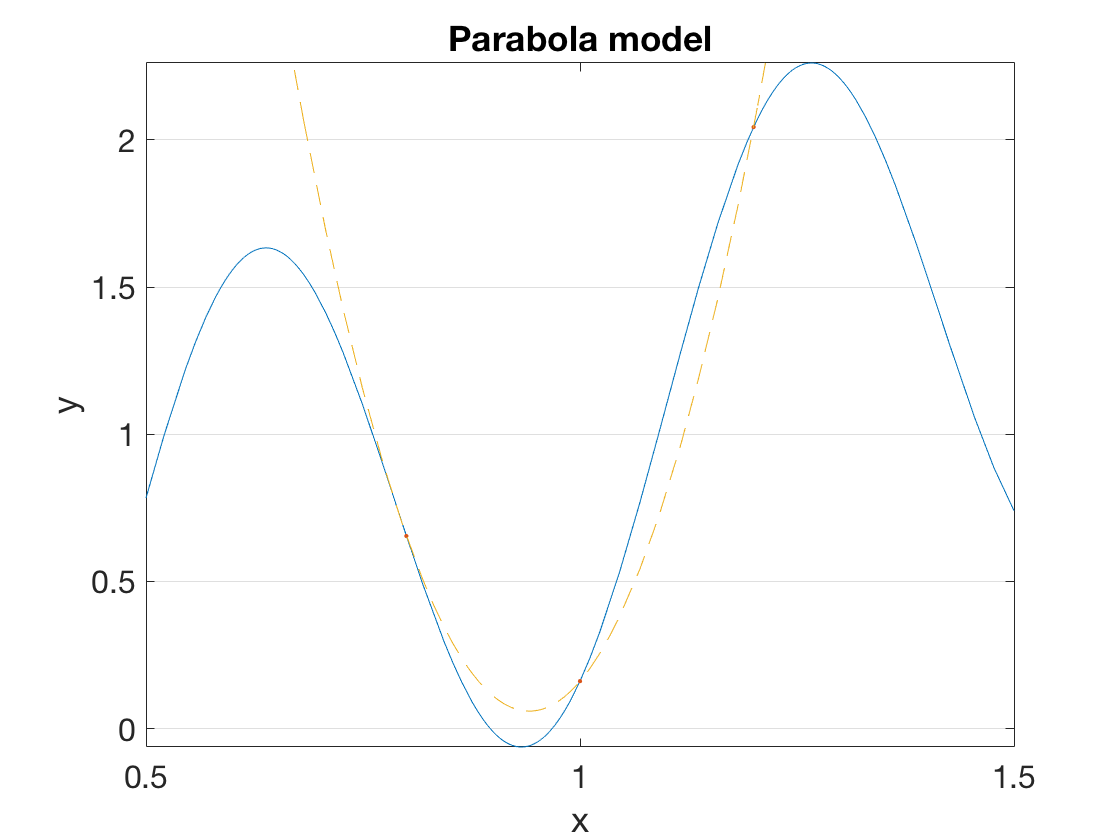

c = polyfit(x,y,2);    % coefficients of interpolant
q = @(x) polyval(c,x);
fplot(q,interval,'--')
title('Parabola model')     % ignore this line

To do inverse interpolation, we swap the roles of $x$ and $y$ in the interpolation.

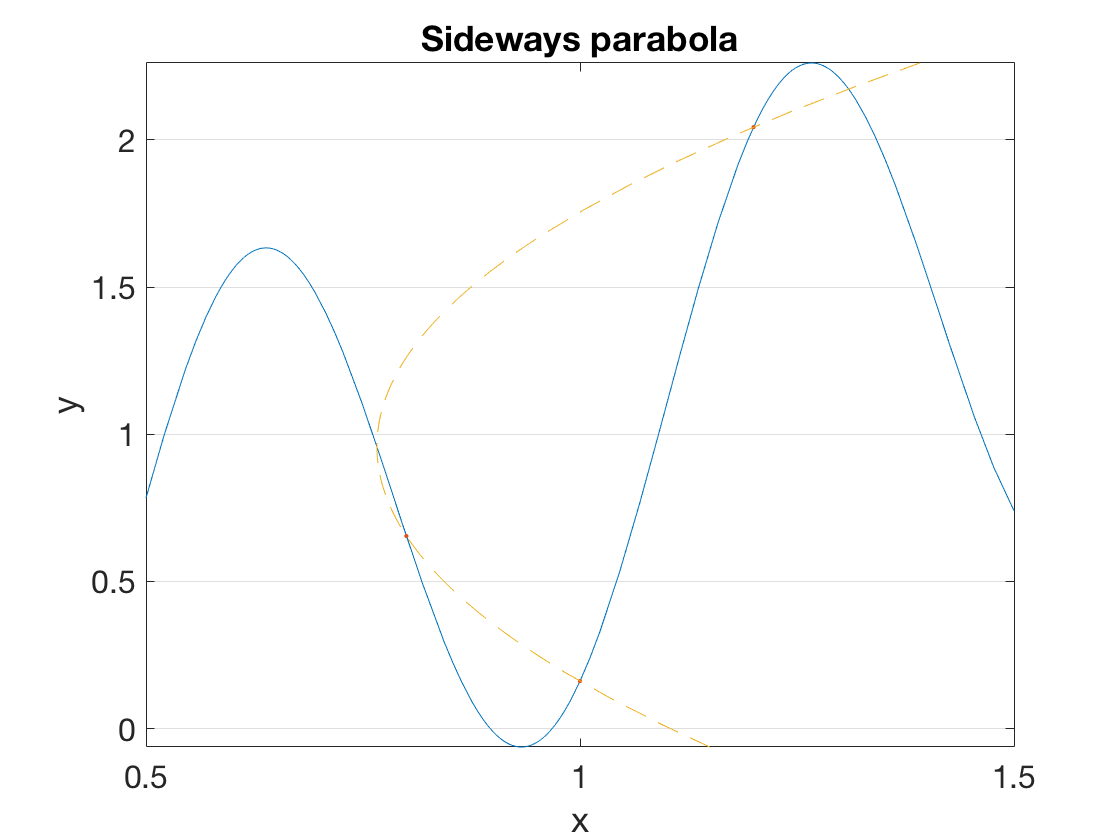

cla, fplot(f,interval), plot(x,y,'.')     % ignore this line
c = polyfit(y,x,2);    % coefficients of interpolating polynomial
q = @(y) polyval(c,y);
fplot(q,@(y) y,ylim,'--')    % plot x=q(y), y=y
title('Sideways parabola')    % ignore this line

We seek the value of $x$ that makes $y$ zero. This means evaluating $q$ at zero. 

x = [x; q(0)];
y = [y; f(x(end))]

y =     0.6545
    2.0439
    0.1609
    1.1482


We repeat the process a few more times.

for k = 4:8
    c = polyfit(y(k-2:k),x(k-2:k),2);
    x(k+1) = polyval(c,0);
    y(k+1) = f(x(k+1));
end

Here is the sequence of errors.

format short e
err = x - r

err =   -1.6789e-01
   2.3211e-01
   3.2112e-02
   1.3609e-01
   1.5347e-02
   3.2683e-03
   4.6174e-04
   6.2958e-06
   3.4390e-09


The error seems to be superlinear, but subquadratic.

logerr = log(abs(err));
ratios = logerr(2:end) ./ logerr(1:end-1)

ratios =    8.1848e-01
   2.3543e+00
   5.8002e-01
   2.0943e+00
   1.3703e+00
   1.3419e+00
   1.5592e+00
   1.6273e+00
